# Short Project: Robotics Surgery

Authors: CATERINA MOLL & MARC GUITART

Team:  G12 - B

Shared Link with the teacher: 

I spect: 1) Pdf file, 2) Videos demostrating your successful task.

Notes. For better undestanding you can split the videos in the meaninful task.

Remember use the options of serial/link plot: 

'workspace' for centering in the surgery task

'zoom' ...  nice puma ratio aspect

'trail'  .. to see the trajectory

etc..

See all at:

>> help SerialLink/plot

## Enviroment

In previous exercise you learned

- How to draw the enviroment: Table, Human, containig Box, etc...

- Derive all the transformation needed

Now the final exercise consist in doing thing the same as happened in the youTube Video of Rosa Robot (https://youtu.be/kPzDq9Tb0uE). 

To infer the Fiducial wrt Robot Rosa I am giving you fiducial wrt {U} (open: Fiducial_wrt_{U}.mat). You must place the Robot Rosa accordingly as happened in the Rosa video. 

It will be no necessary to draw the enviroment. I am giving you the figure that contain Table, Human and the fiducials: Enviroment_Short_Project.fig

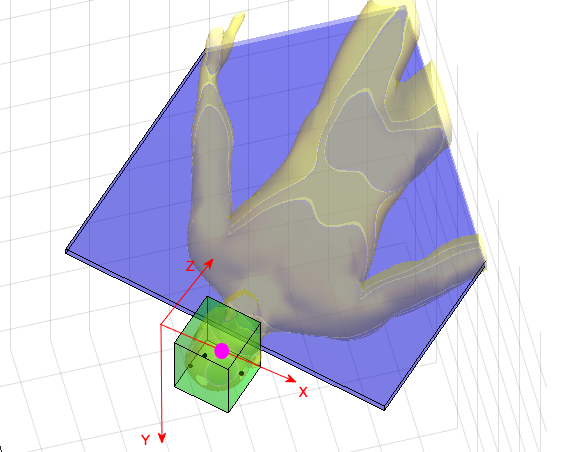

Enviroment given by the teacher.

## Robot placement (5%)

- Open the figure: Enviroment_Short_Project.fig and play with the views.

- Decide the Robot Reference Frame, i.e. location of the Robot Base

- Use 'p560.base=transl(x,y,z) to place the Robot Puma such that the human head is reacheable

close all
openfig('Enviroment_Short_Project.fig','visible');
hold on
x = 5.2;
y = 10;
z = 0.8;
mdl_puma560
p560.base=transl(x, y, z)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, fastRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (5.2, 10, 0.8), RPY/xyz = (0, 0, 0) deg             
 


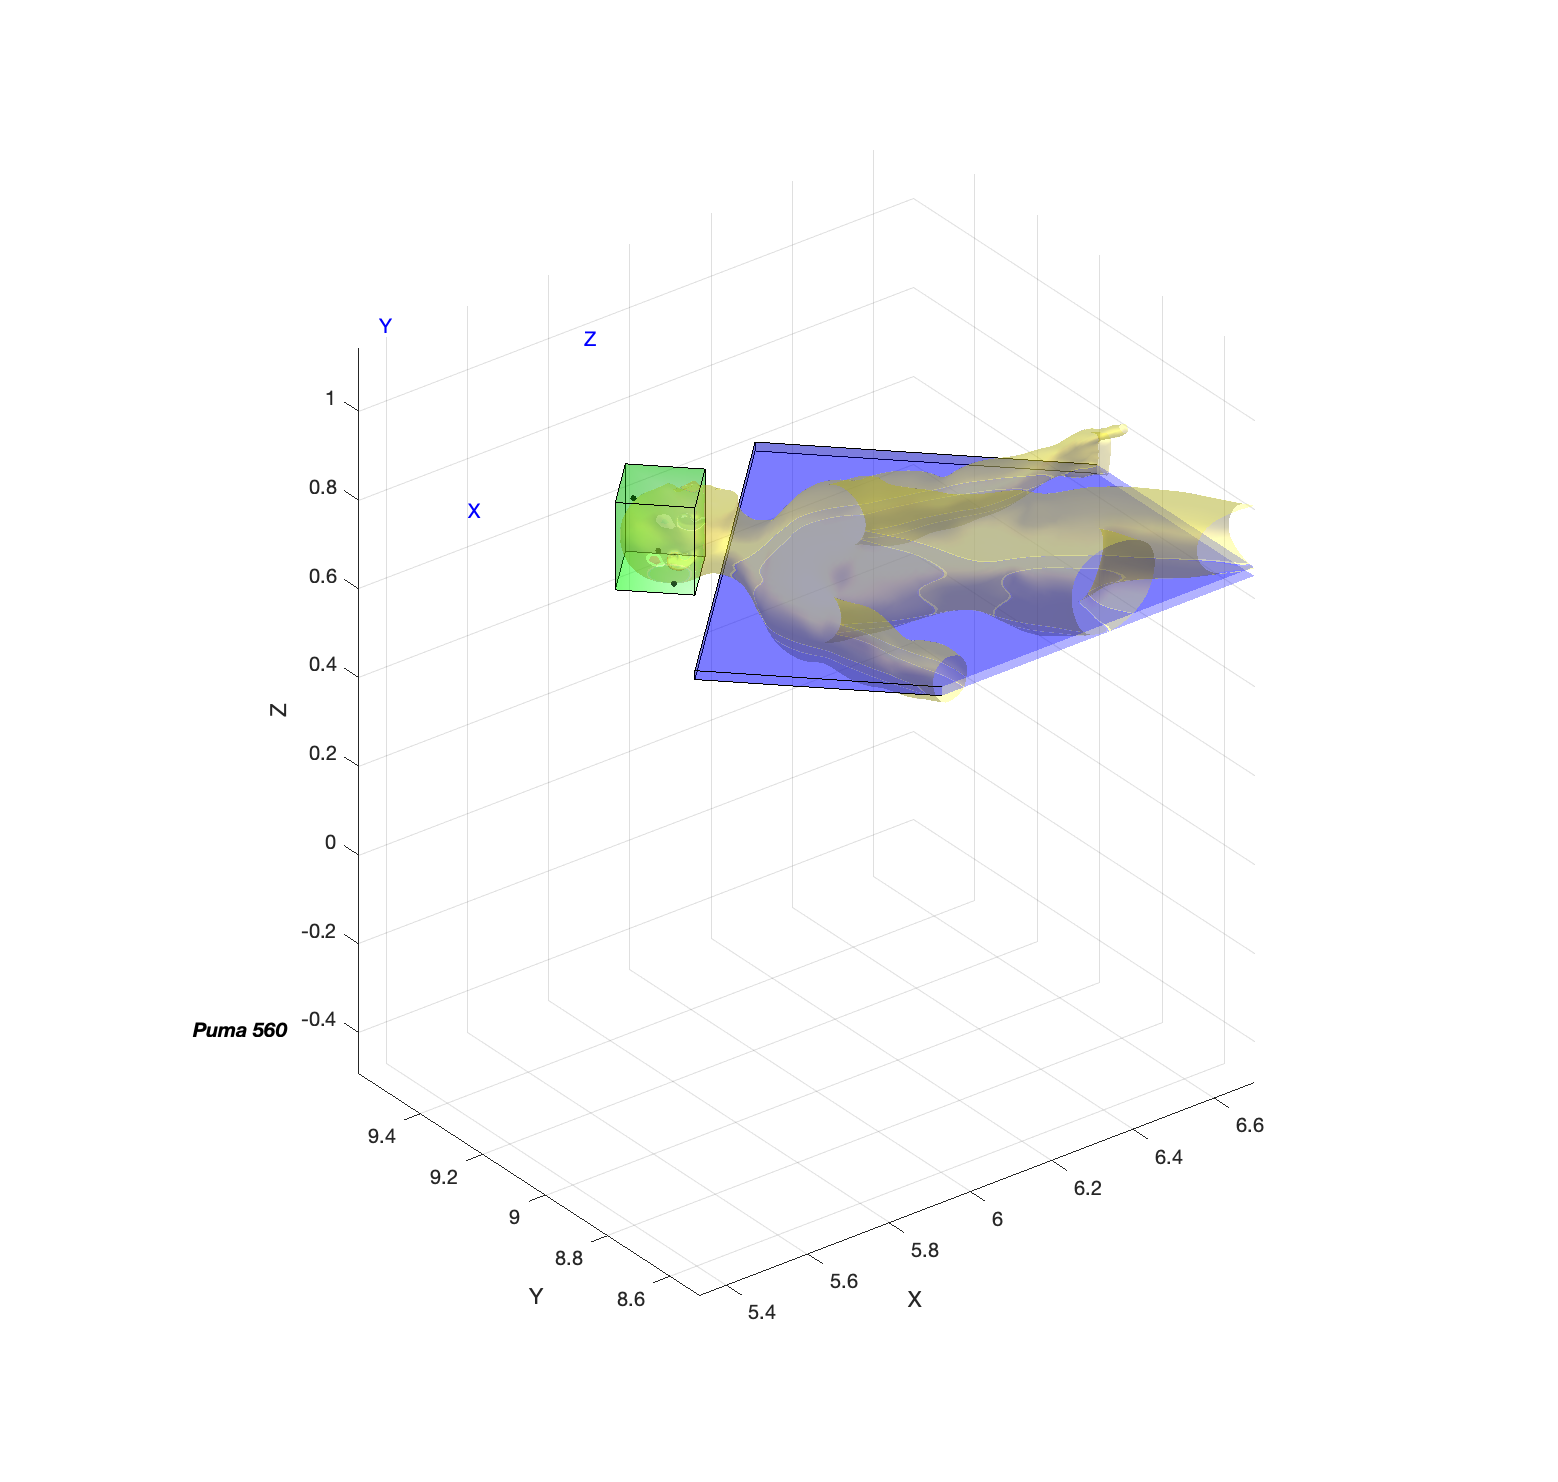

%p560.base=p560.base.T * trotz(-pi/4) 
%p560.tool=transl(0,0,0.25) lo haremos mas adelante
p560.plot(qn, 'zoom', 1.5)

## 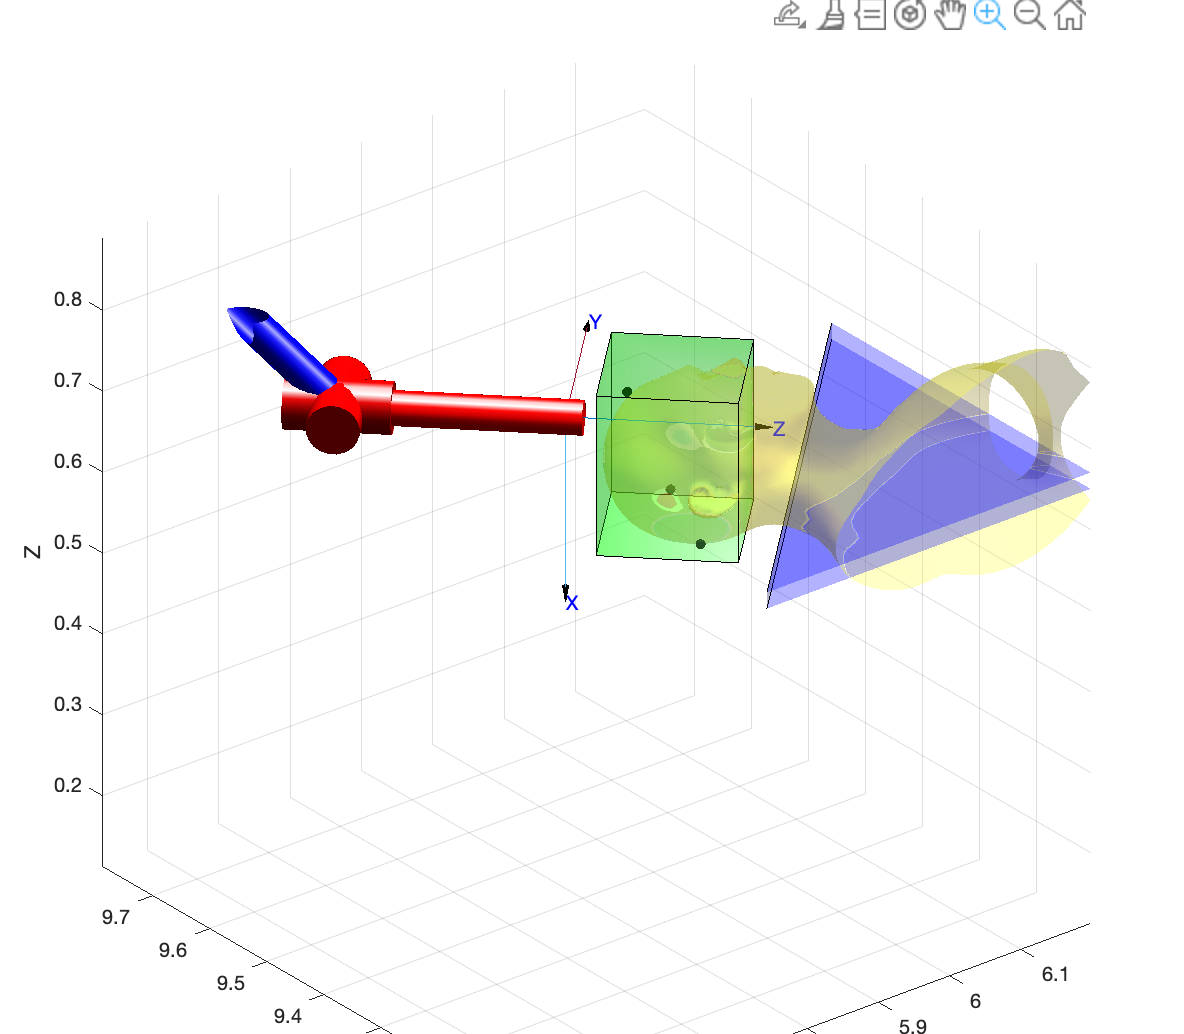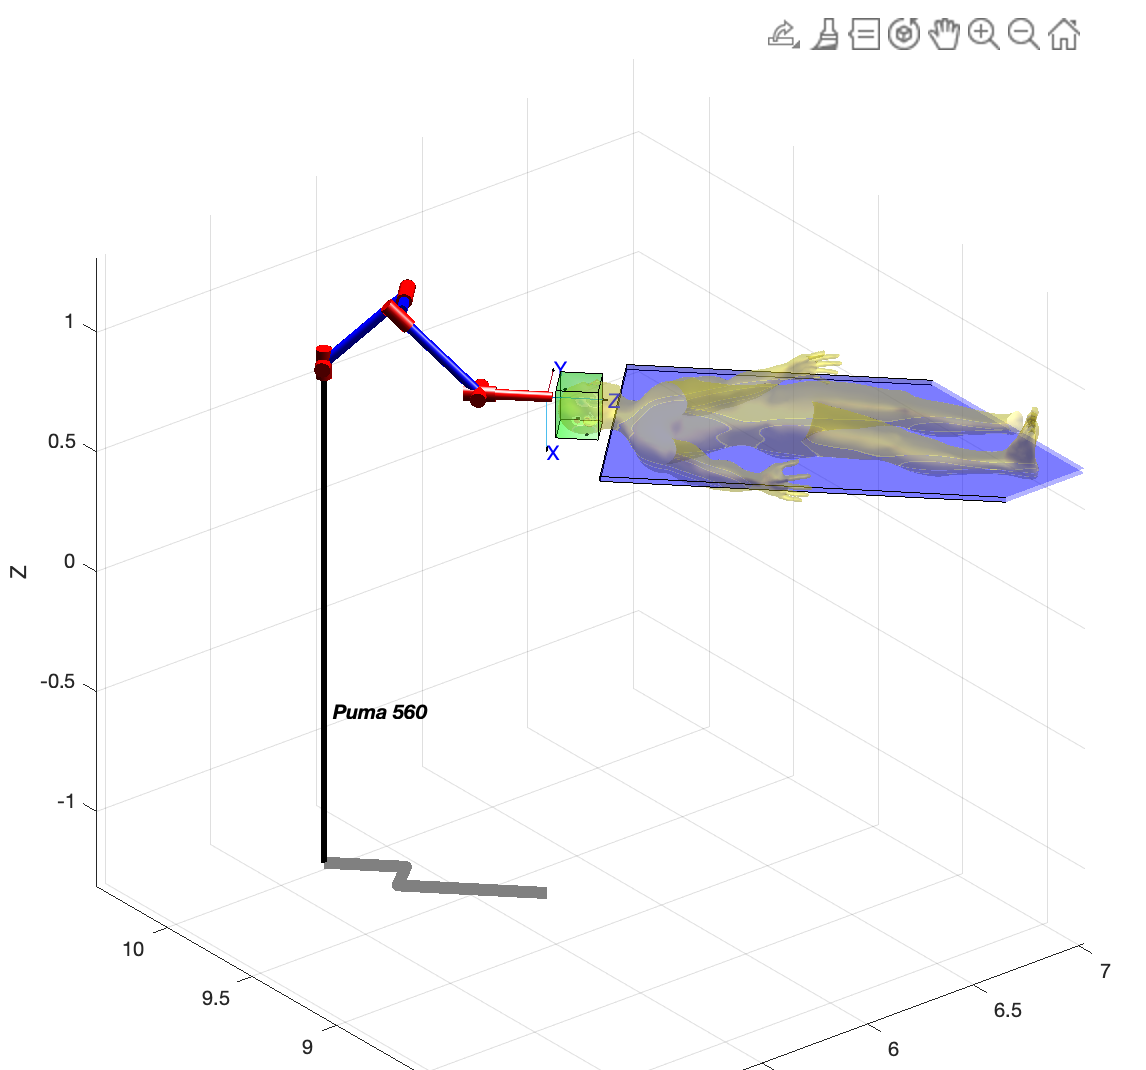

Enviroment + robot placement

## Transformations needed (10%)

- Enumerate the transformation you will need to draw object in Reference Frame Univers: RF{U}

We will nead to draw the Reference Frame Univers ; univers{U}, robot{R}, fiducials{F}, dicon imatges{I}

Also the next transformation:*U**R**T(univers-robot) *,*R**F**T(fiducials-tumor)*,*F**I**T(fiducials-imatges) a**n**dv R**I**T(robot- imatges)*

It is clear that we will need the transformation Image to Robot, i.e. *R**I**T* to correctly make the tumor surgery.let's do it :)

            2.  Compute them; 

let's do it :)

(put your code Here)

###  UNIVERS - ROBOT

T_Robot_Univers = transl(x, y, z); %position of the robot with {U}

We have the fiducials cordinates wrt{U}

To do all the transforms compons is important to remeber this image:

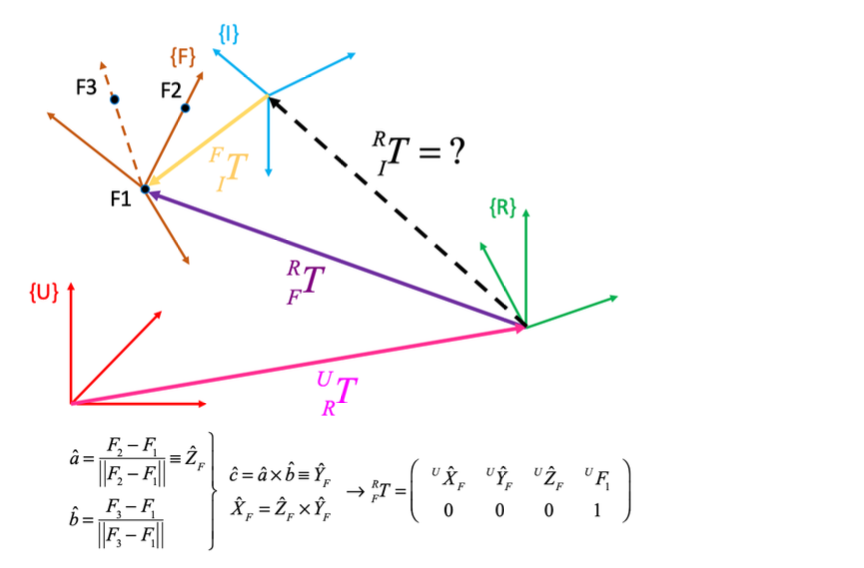

**FIDUCIAL - ROBOT**

We have the fiducials cordinates wrt{U}, and we multiplicate with the T_R_U calculate before to transform as a robot cordinates.

%doble click to charge the Fiducial_wrt_{U}  
Fiducials_Robot=inv(T_Robot_Univers)*[F1 F2 F3;ones(1,3)];

orientation wrt{R}

Yf = (Fiducials_Robot(1:3,2)-Fiducials_Robot(1:3,1))/norm(Fiducials_Robot(1:3,2)-Fiducials_Robot(1:3,1));
b=(Fiducials_Robot(1:3,3)-Fiducials_Robot(1:3,1))/norm(Fiducials_Robot(1:3,3)-Fiducials_Robot(1:3,1));
Zf = cross(Yf,b)/norm(cross(Yf,b));
Xf = cross(Yf,Zf)/norm(cross(Yf,Zf));

hand made frame description:

T_Fiducials_Robot = [[Xf;0] [Yf;0] [Zf;0] [Fiducials_Robot(:,3)]];


calculem per passar dibuixar RF{U} els fidicials

 T_Fiducials_Univers=T_Robot_Univers*T_Fiducials_Robot;

## Fiducials wrt {I} 

Taking data from Dicom images

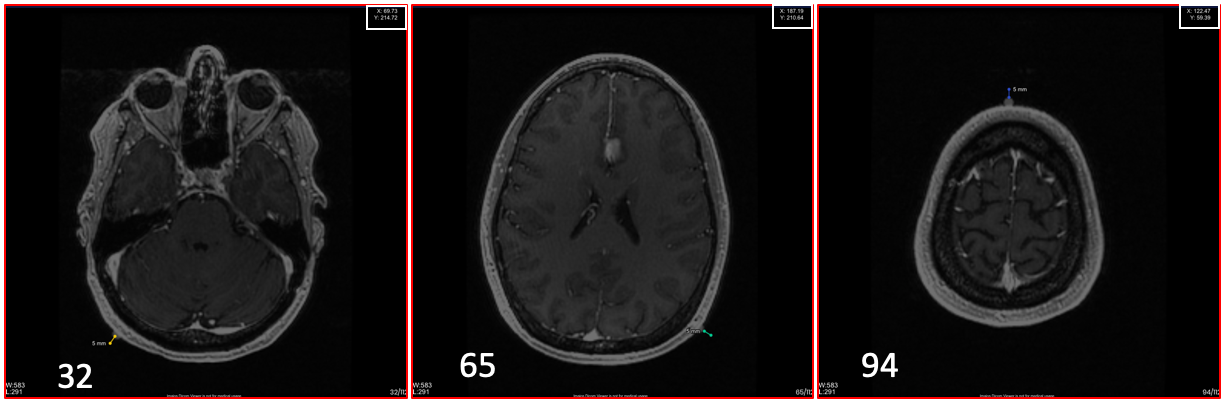

pitch = 1.4; % Pitch among slices
F1D = [0.06777 0.19902 0.032*pitch]'; %image #32
F2D = [0.17304 0.19607 0.065*pitch]'; %image #65
F3D = [0.11491 0.05867 0.094*pitch]'; %image #94
Tumor = [0.12241 0.09782 0.078*pitch]'; %image #78


## T_F_I - Frame Description 

As we mention before It is needed to use the Fiducial as auxiliary Reference Frame 

Extracted from the triangle F1D - F2D - F3D

Same procedure as before with the fiducial in RF {U}

### Orientation 

YfD = (F2D - F1D)/norm(F2D - F1D);
b = (F3D - F1D)/norm(F3D - F1D);
ZfD = cross(YfD,b)/norm(cross(YfD,b));
XfD = cross(YfD,ZfD)/norm(cross(YfD,ZfD));

### Frame Description  

${}_F^I{T$ take the Fiducial 1 as ${}^A{P_{BORG}}$ in our case A is RF{I}

T_Fiducials_Imatges = [[XfD;0] [YfD;0] [ZfD;0] [F3D;1]]

T_Fiducials_Imatges =     0.1827    0.9154    0.3587    0.1149
    0.9158   -0.0257   -0.4009    0.0587
   -0.3577    0.4017   -0.8430    0.1316
         0         0         0    1.0000


%det(T_Fiducials_Imatges) we have use it to check that is corret the
%transform compon

**IMATGES - UNIVERS ; IMATGES - ROBOT**

T_Imatges_Univers= T_Fiducials_Univers*inv(T_Fiducials_Imatges);
T_Imatges_Robot=inv(T_Robot_Univers)*T_Fiducials_Univers*inv(T_Fiducials_Imatges)

T_Imatges_Robot =     0.7340   -0.0264   -0.6787    0.5554
    0.6791    0.0189    0.7338   -0.9176
   -0.0066   -0.9995    0.0318    0.0686
         0         0         0    1.0000


## Draw Image Reference Frame and Tumor (20%)

Add to the figure the Image Reference Frame and the tumor. Review previous exercises delivered

Use best scale to see it, (option: 'length' of 'trplot' function).

Expected result

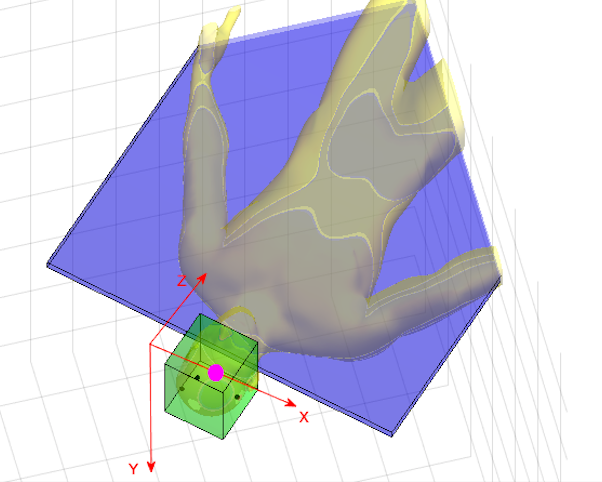

  T_Imatges_Univers = T_Imatges_Univers * troty(pi) * transl(-0.25,-0.05,-0.2)

T_Imatges_Univers =    -0.7340   -0.0264    0.6787    5.8045
   -0.6791    0.0189   -0.7338    9.3980
    0.0066   -0.9995   -0.0318    0.9233
         0         0         0    1.0000


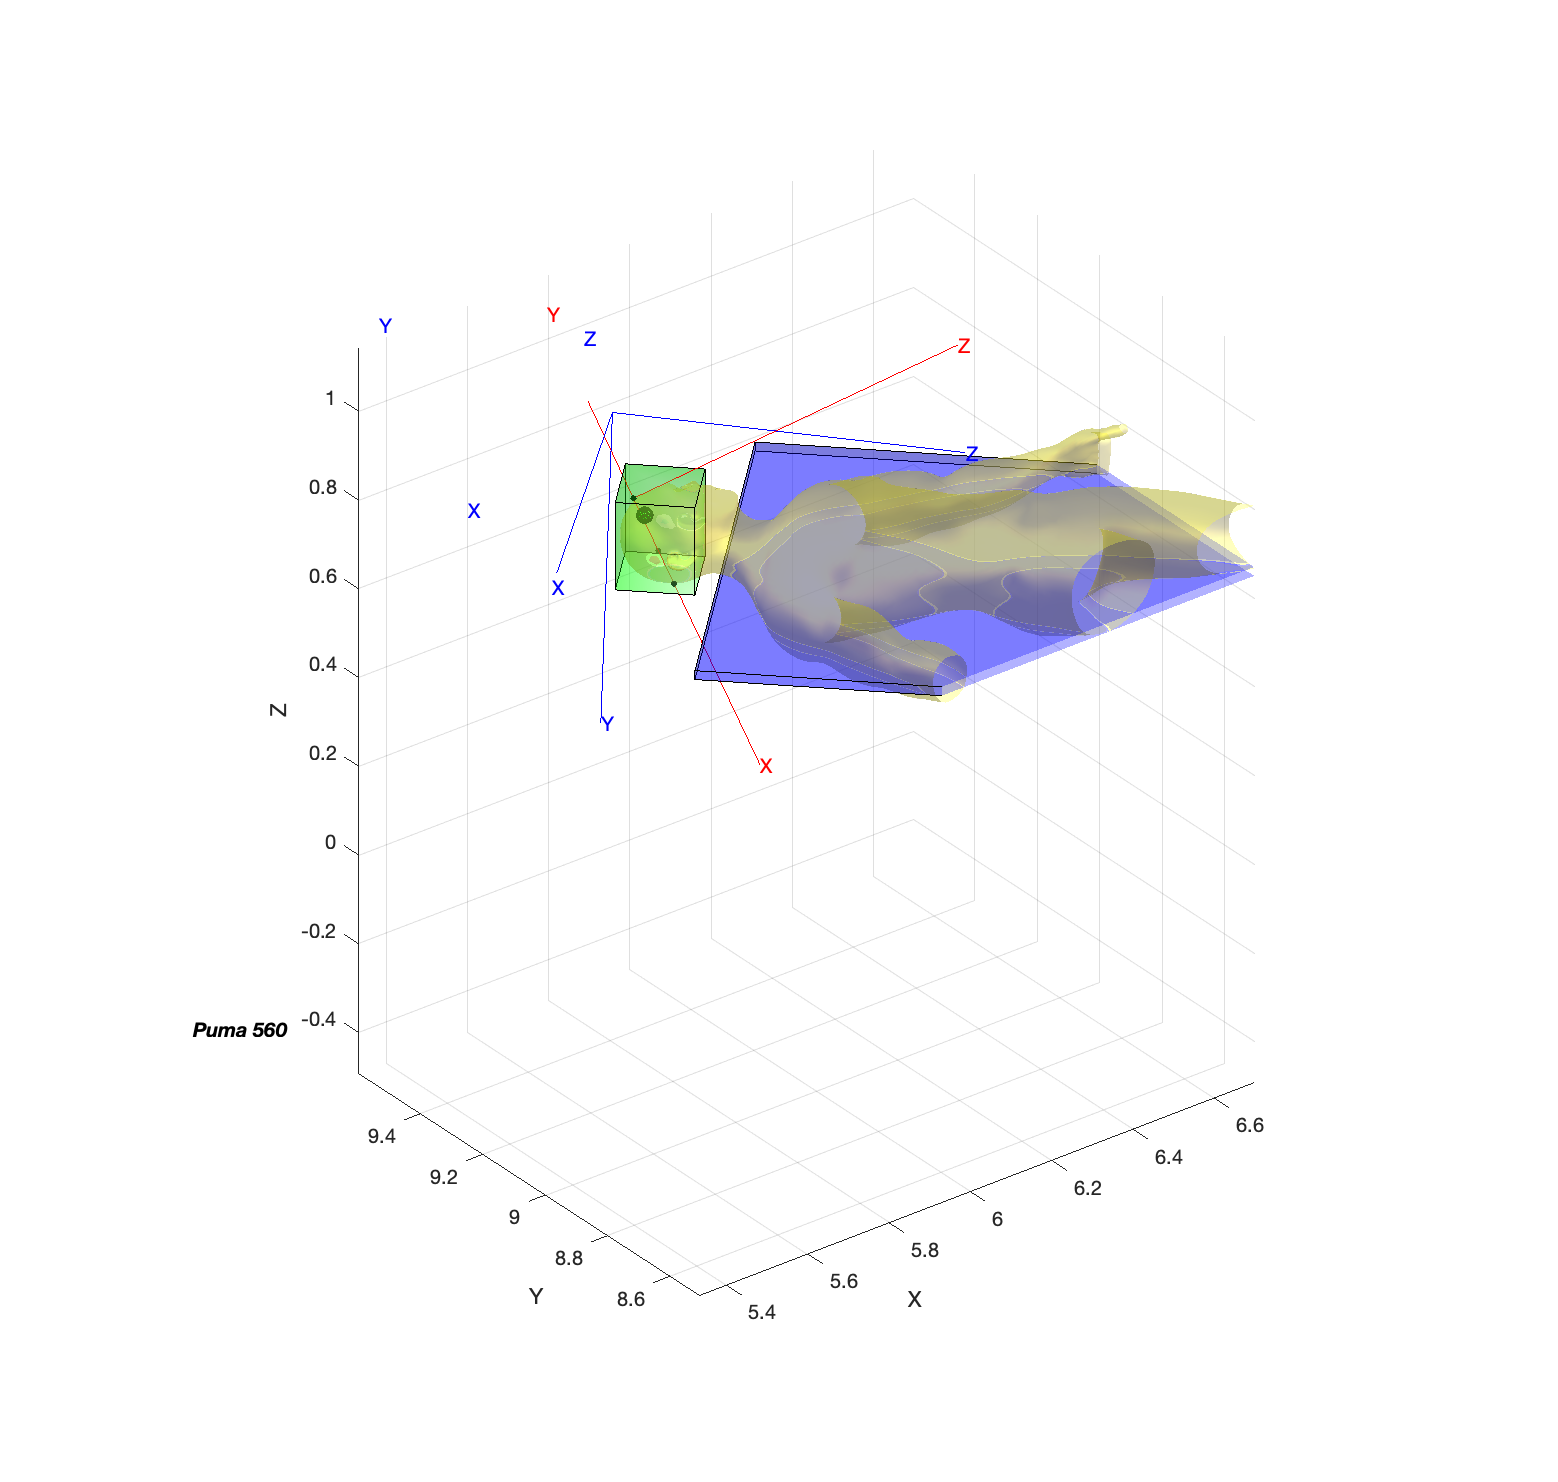

trplot(T_Imatges_Univers,'Frame','I','color', 'blue','length',0.7)
trplot(T_Fiducials_Univers,'Frame','F','color', 'red','length',0.7)
Tumor_R = T_Imatges_Robot * [Tumor;1];
Tumor_U = T_Robot_Univers * T_Imatges_Robot * [Tumor;1];
[X,Y,Z] = sphere;
Diam = 0.0324;
rt = Diam/2;
surf(X*rt + Tumor_U(1), Y*rt + Tumor_U(2), Z*rt + Tumor_U(3), 'FaceColor',[0 1 0])

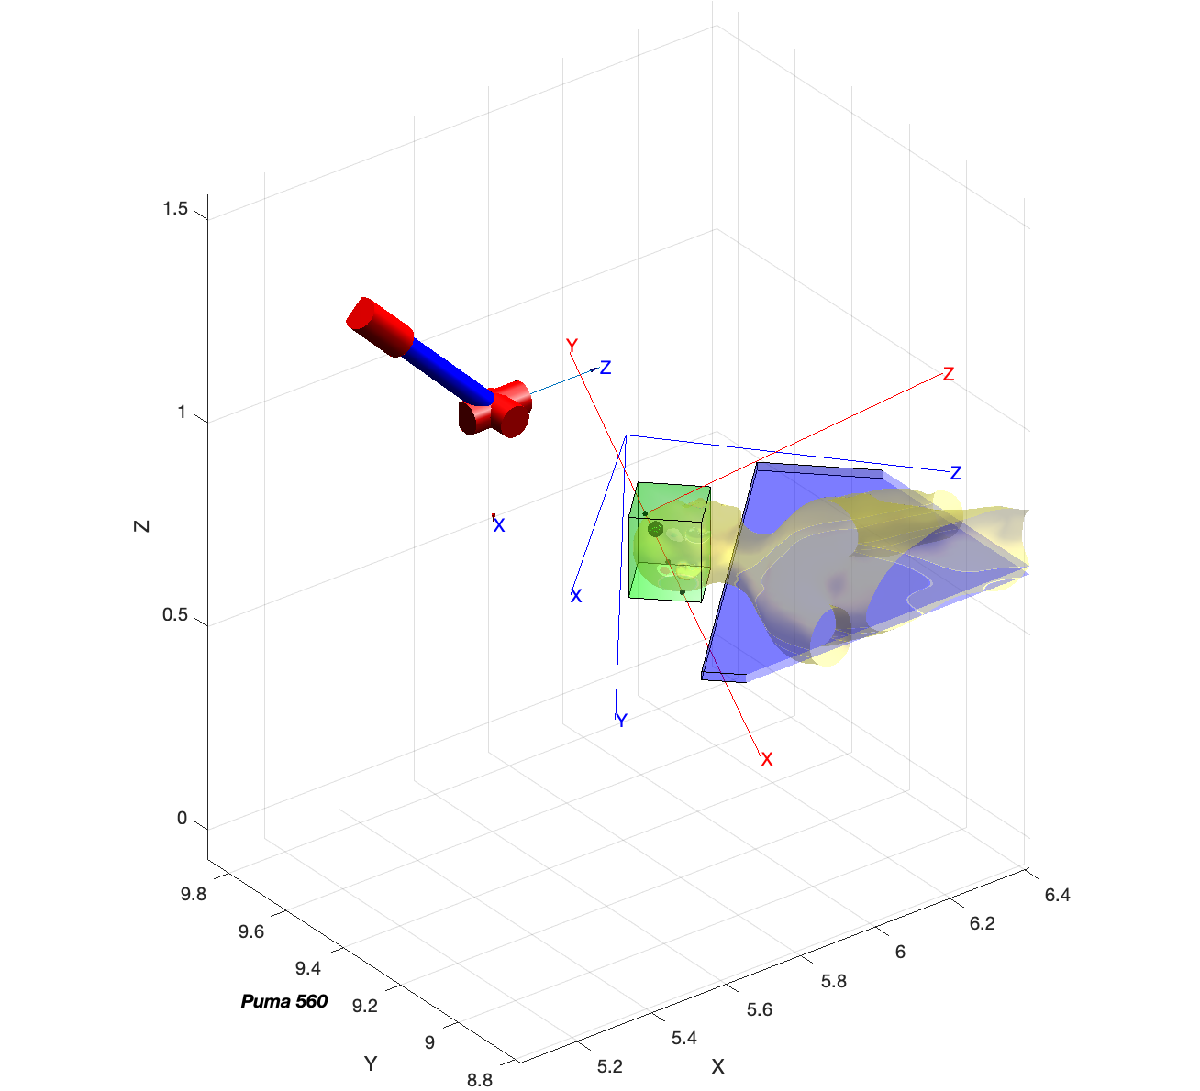

## Biospy (20%)

The last Laboratory class I helped you in breaking down the steps needed to perform this Robotic task

Review the snapshot of the blackboard: Guio conceptual per fer la Biopsia in ATENEA: [https://atenea.upc.edu/mod/resource/view.php?id=4255002.](https://atenea.upc.edu/mod/resource/view.php?id=4255002.)

Prepare a script that perform a biopsy making the necesary subsection.

Zoom in the scene and record a video with the best view.

Take into account:

- Use a tool that has the following Transformation: p560.tool=transl(0.0 0 0.25)

- Use 'trail' option of plot to visualize the trajectory.

- The speed of biopsy function that you design ought to be a parameter to satisfy the surgeons. Review 'ctraj' function explained in theory of trajectory: 

Answer these questions:

- Display in a figure the displacement, velocity and aceleration of the tool in End Efector Reference frame.

- How much enter the tool in the patient brain.

- What are the speed of the tool in Wordl Reference Frame. (Review Jacobians theory).

Understand the 'mlx' file: Puma_doing_task_example_1.mlx that I am giving you as a example.

 p560.tool=transl(0, 0, 0.25)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, fastRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (5.2, 10, 0.8), RPY/xyz = (0, 0, 0) deg             
tool:    t = (0, 0, 0.25), RPY/xyz = (0, 0, 0) deg               
 



INI = transl(Tumor_U(1:3)) %pose of tumor center

INI =     1.0000         0         0    5.7686
         0    1.0000         0    9.2475
         0         0    1.0000    0.7735
         0         0         0    1.0000


t1 = INI*transl(-0.2,0.2,0)*trotz(pi/4)*trotx(pi/2)*trotz(-pi/2)

t1 =          0    0.7071    0.7071    5.5686
         0    0.7071   -0.7071    9.4475
   -1.0000         0         0    0.7735
         0         0         0    1.0000


t2 = INI*trotz(pi/4)*trotx(pi/2)*trotz(-pi/2)

t2 =          0    0.7071    0.7071    5.7686
         0    0.7071   -0.7071    9.2475
   -1.0000         0         0    0.7735
         0         0         0    1.0000


t3 = INI*transl(-0.03,0.03, 0)*trotz(pi/4)*trotx(pi/2)*trotz(-pi/2)

t3 =          0    0.7071    0.7071    5.7386
         0    0.7071   -0.7071    9.2775
   -1.0000         0         0    0.7735
         0         0         0    1.0000


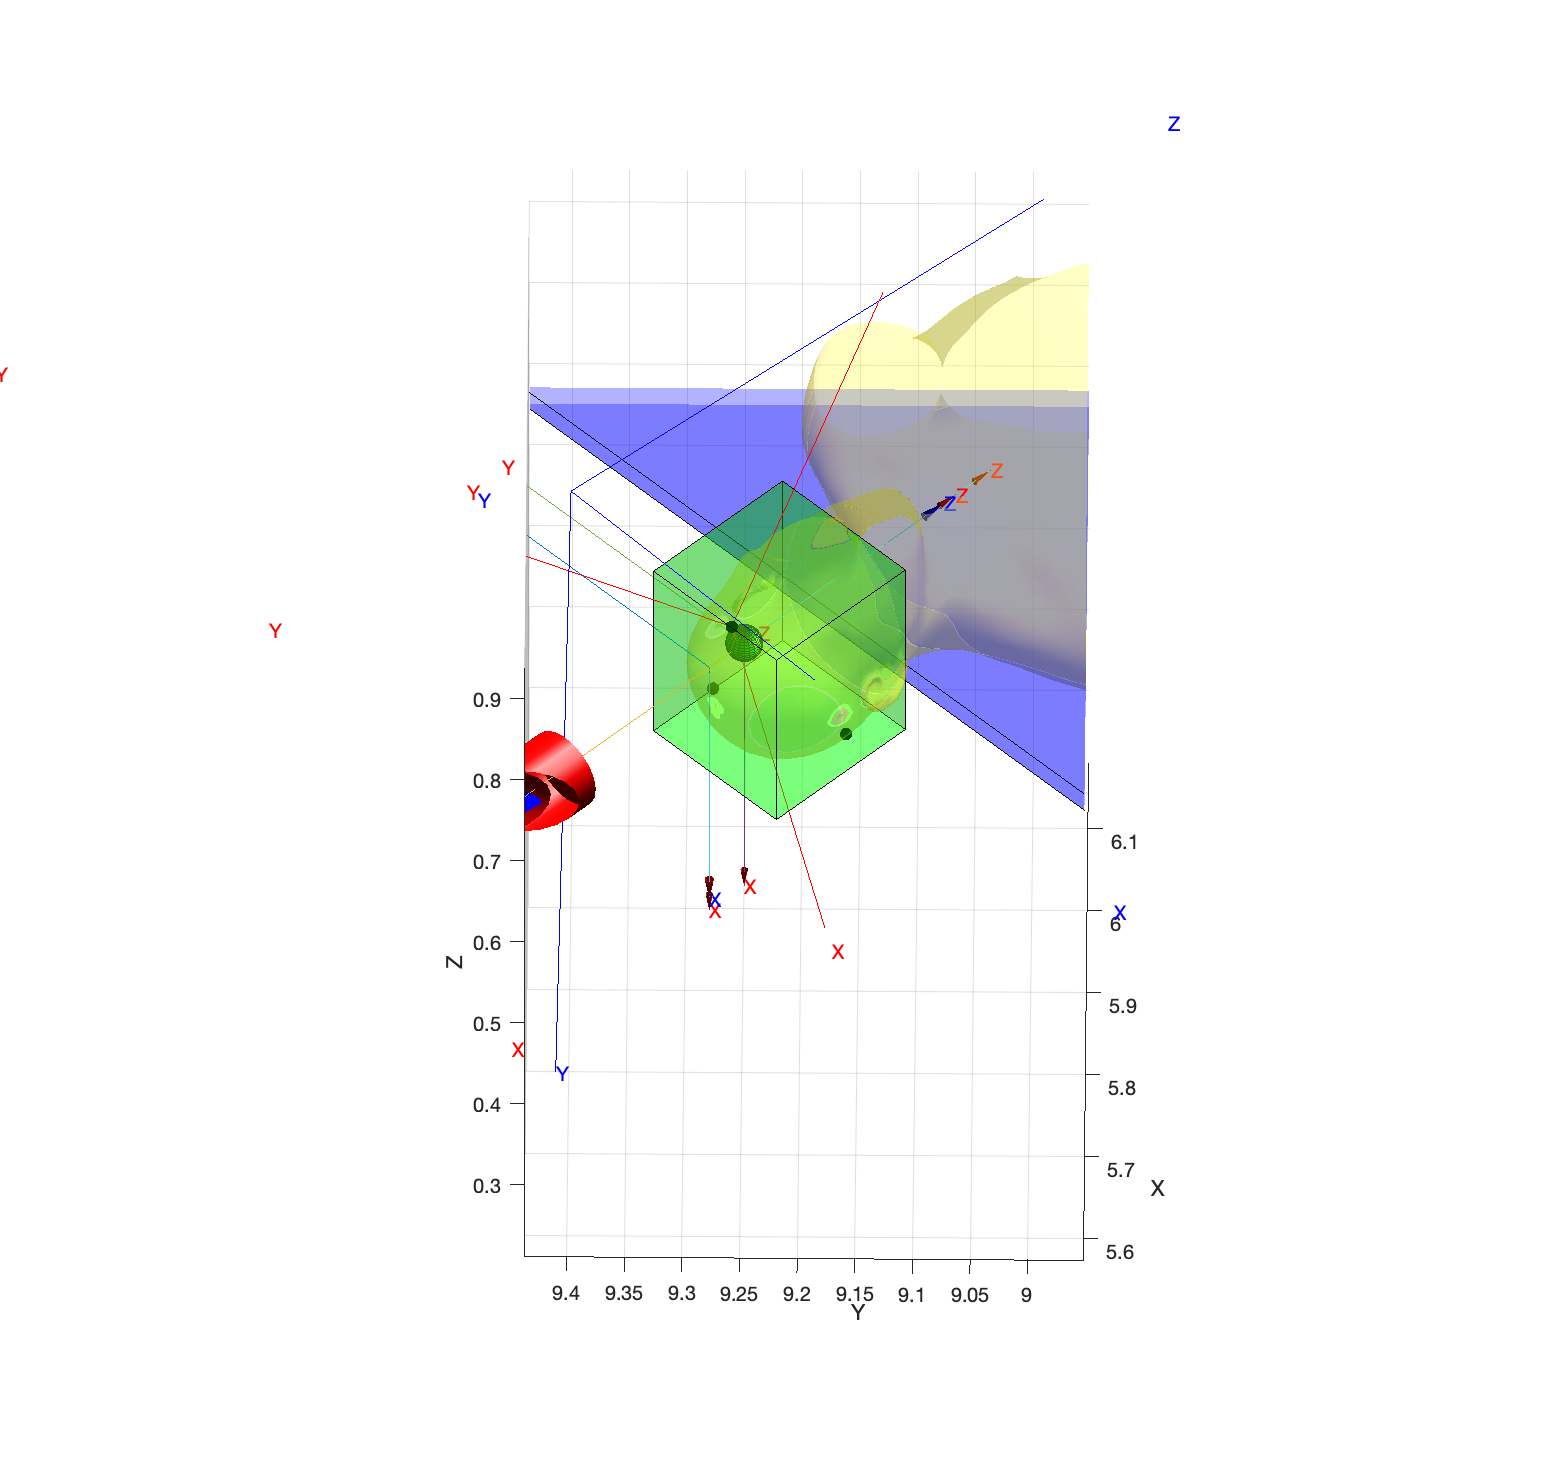

trplot(t1,'length',0.3, 'arrow', 'width', 0.2, 'color', 'r')
trplot(t2,'length',0.3, 'arrow', 'width', 0.2, 'color', 'r')
trplot(t3,'length',0.3, 'arrow', 'width', 0.2, 'color', 'r')

T0 = p560.fkine(qn);
q_0 = p560.ikine6s(T0,'run');
q_1 = p560.ikine6s(t1,'run');
t_0 = linspace(0,3,30); % temps, fem que vagi de 0 a 3 passant per 30 punts
Q_0=jtraj(q_0,q_1,t_0); %vagi dun punt a l altre amb el temps especificat adalt

t_1=linspace(0,5,50); %augmentant el 50 o disminuint canviem la velocitat
[S,SD,SDD]=tpoly(0,1,t_1);
S(1)=0;
S(end)=1; %pel bug que hi havia

T_1_2 = ctraj(t1,t2,S);
Q_1 = p560.ikine6s(T_1_2);


T_2_3 = ctraj(t2,t3,S);
Q_2 = p560.ikine6s(T_2_3);
QT=[Q_0;Q_1; Q_2];
view(-90, 45)
p560.plot(QT,'zoom',1.5,'trail', {'r', 'LineWidth', 1.5});

## Trepanation (25%)

Define a Hole Reference Frame such that the its z unitary vector points to tumor center 

Perform the trepanation such that the Z unitary vector of the End Effector (Z_u_ee), that is the tool form 45º along all the trajectoy with respect Z unitary vector of the Hole Reference Frame (Z_u_h). The hole must be litle bit less than the Tumor diameter. 

To check you did well: dot product of Z_unitaries vector allway form the 45º

Zoom in the scene and record a video with the best view.

Prepare a script that perform a tepranation making the necesary subsection.

Take into account:

Use a tool that has the following Transformation: p560.tool=transl(0.0 0 0.25)

Use 'trail' option of plot to visualize the trajectory.

Answer these questions:

1.- Display in a figure the lineal displacement, velocity and aceleration of the tool in End Efector Reference Frame.

2.- Display in a figure the manipulabitlity of the trepanation function either for translation and rotation. (Review Jacobians Theory)

3.- Find an alternate robot location for improving your manipulabitity.

Understand the 'mlx' file: Puma_doing_task_example_2.mlx, that I am giving you as a example

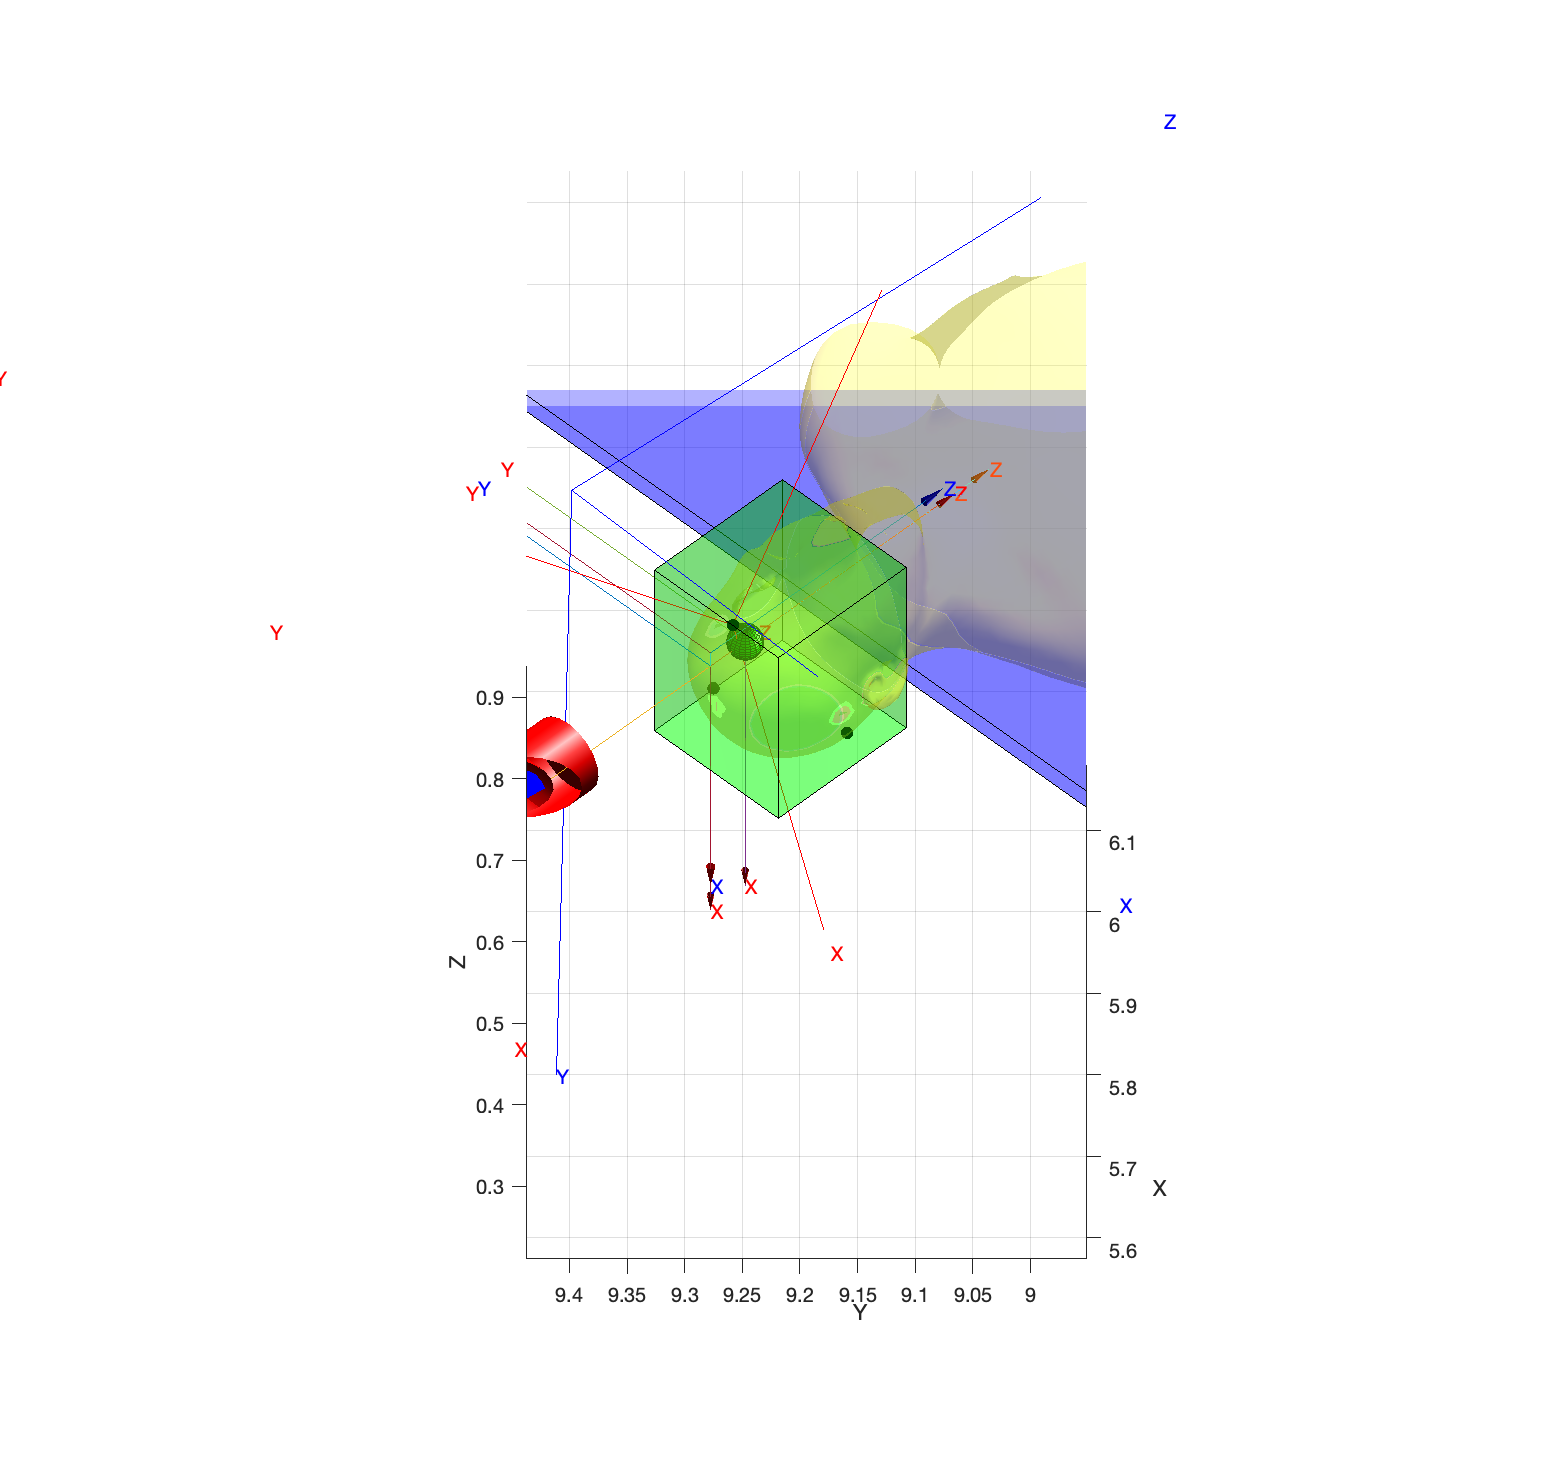

n=200;
p560.tool=transl(0.0, 0, 0.25);
for i=1:n
Laser_Pose(:,:,i)= INI*transl(-0.03,0.03, 0)*trotz(pi/4)*trotx(pi/2)*trotz(-pi/2)*trotz(2*pi*i/n)*transl(-rt, 0, 0);
end
Q= p560.ikine6s(Laser_Pose, 'run');
p560.plot(Q,'view',[-90 45],'trail','-','jaxes','zoom',2);

## Tumor burning (20%)

If the Surgeon decision is to burn the tumor the hole to enter the tool ought be diameter 10 mm.

Prepare a script that perform tumor burning with the laser.  Zoom in the scene and record a video with the best view.

You ought to think in an algorithm, that in order, fill up the tumor's  equivalent sphere with small burning spheres of 4mm diameter.

Use a tool that has the following Transformation: transl(0 0 0.2)

Answer these questions:

1.- Display in a figure the lineal displacement, velocity and aceleration of the tool in End Efector Reference frame doing the Task.

2.- How long it takes your burning function to burn the tumor.

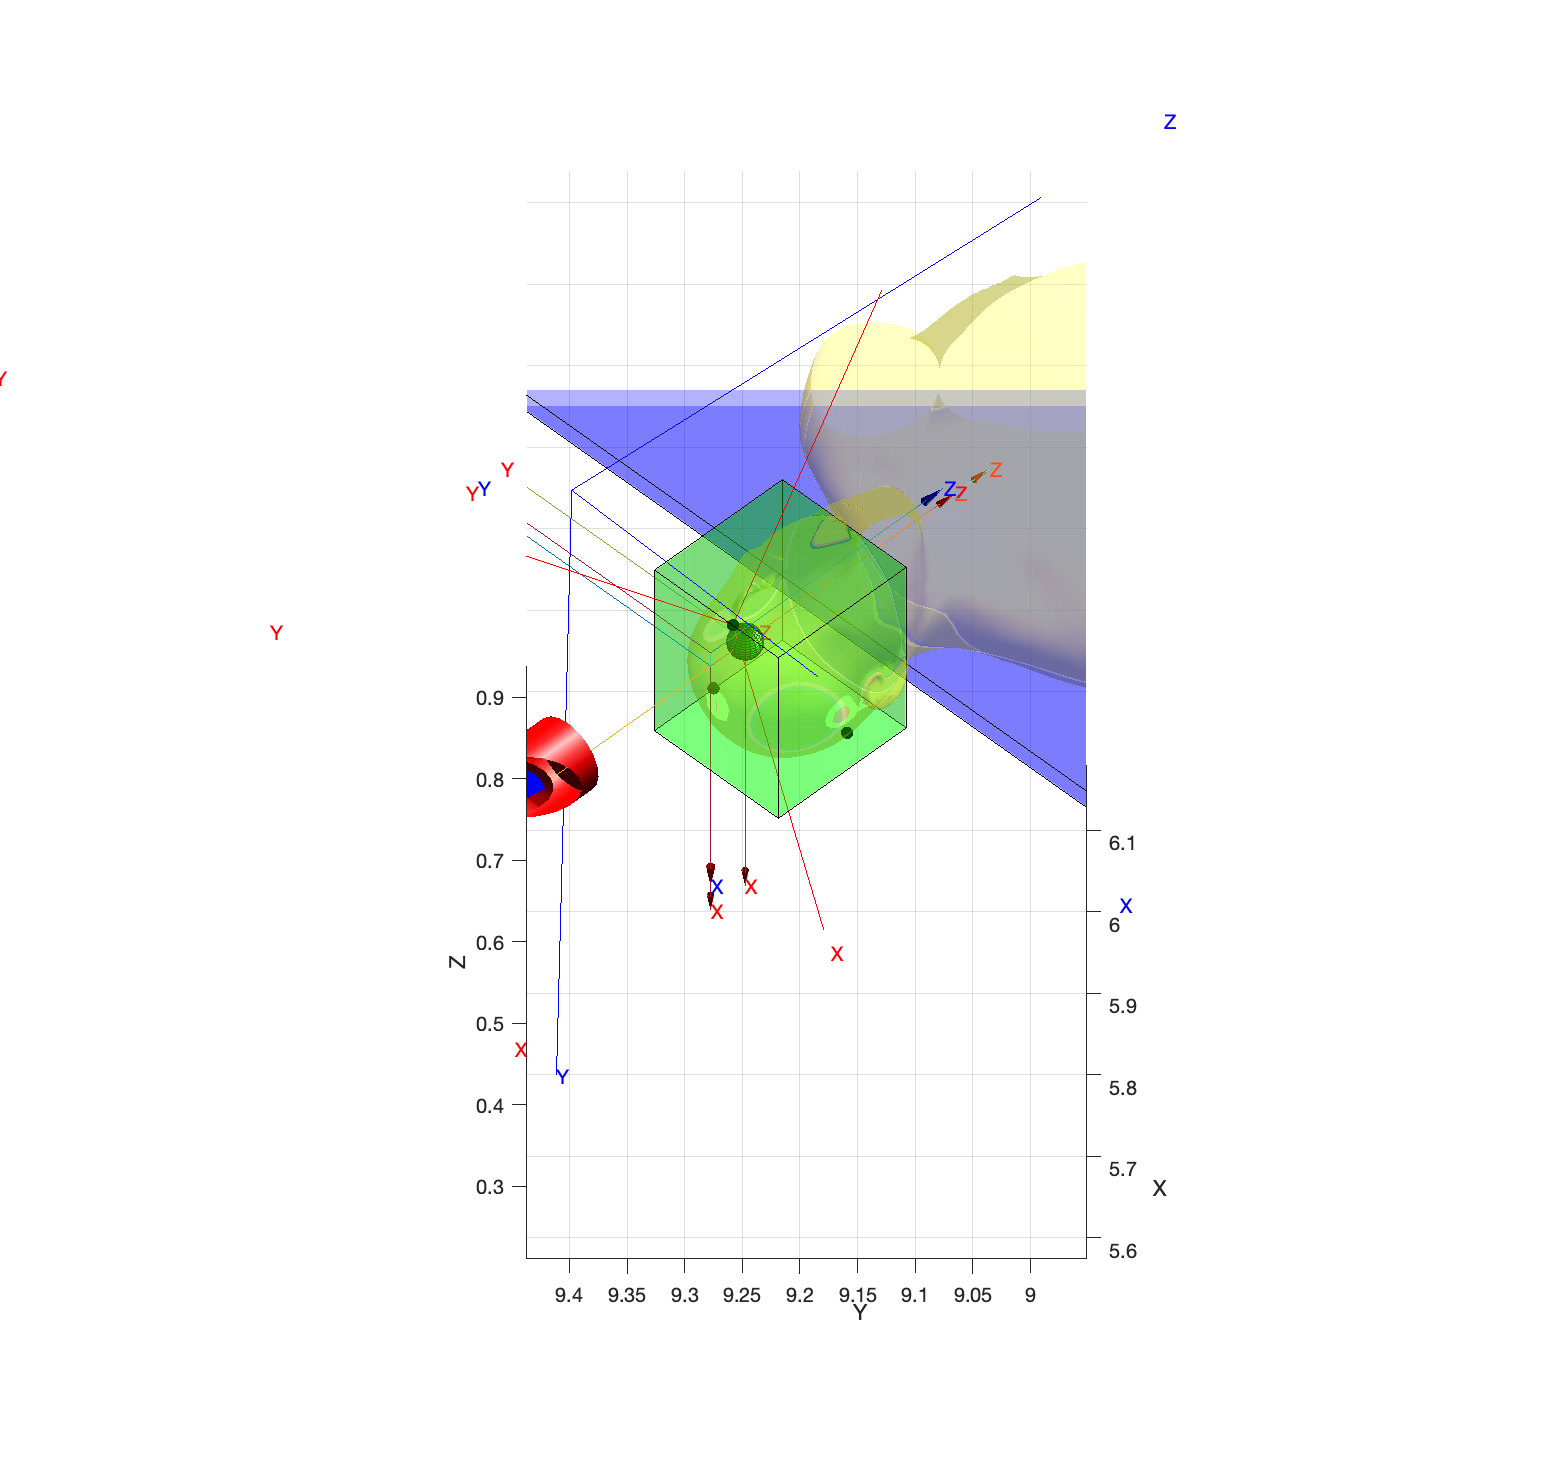

p560.tool=transl(0.0, 0, 0.2);
radi_t = 0.005;  % Radi del tumor (5 mm)
r_es = 0.002;  % Radi de les  esferes petites (2 mm)
volumenTumor = (4/3) * pi * (radi_t^3);
volumenEsfera = (4/3) * pi * (r_es^3);
numEsferas = floor(volumenTumor / volumenEsfera); 
numFilas = floor(2 * radi_t/ (2 * r_es));
numColumnas = numFilas;
numAlt = numFilas;
spacing = 2 * r_es;
esferaPos = zeros(4,numEsferas);
index = 1;
for i = 1:numFilas
    for j = 1:numColumnas
        for k = 1:numAlt
            x = (i - 1) * spacing - radi_t + r_es;
            y = (j - 1) * spacing - radi_t + r_es;
            z = (k - 1) * spacing - radi_t + r_es;
            esferaPos(:, index) = T_R_U * T_I_R * [x, y, z, 1]'+[Tumor;1];
            index = index + 1;
        end 
    end
end
scatter3(esferaPos(1, :), esferaPos(2, :), esferaPos(3, :), 'filled');